Canny ridge filter testing

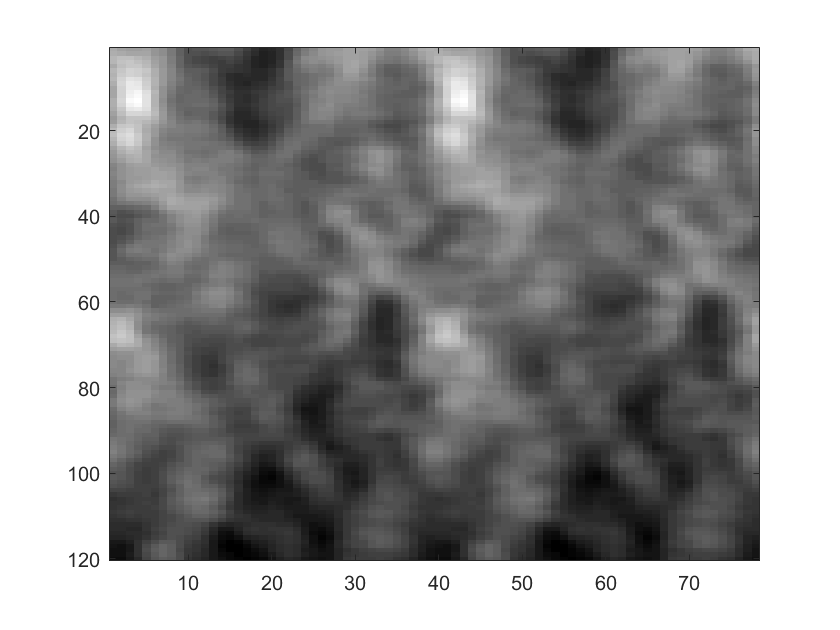

fname1 = '..\testing\testKymographs\SM1_JF-549_500ms.exp_50.Power_100x6s_3_MMStack_Pos0.ome_denoise_reg_ring15_kymoWrap.tif';
fname2 = '..\testing\testKymographs\180327_Sam1_1mW_RingHiLO_1_MMStack_Pos0.ome_denoise_reg_ring1_kymoWrap.tif';

im = imread(fname2);
im(end,:)=[];%remove the last black (non-data) row
imagesc(im);
colormap gray

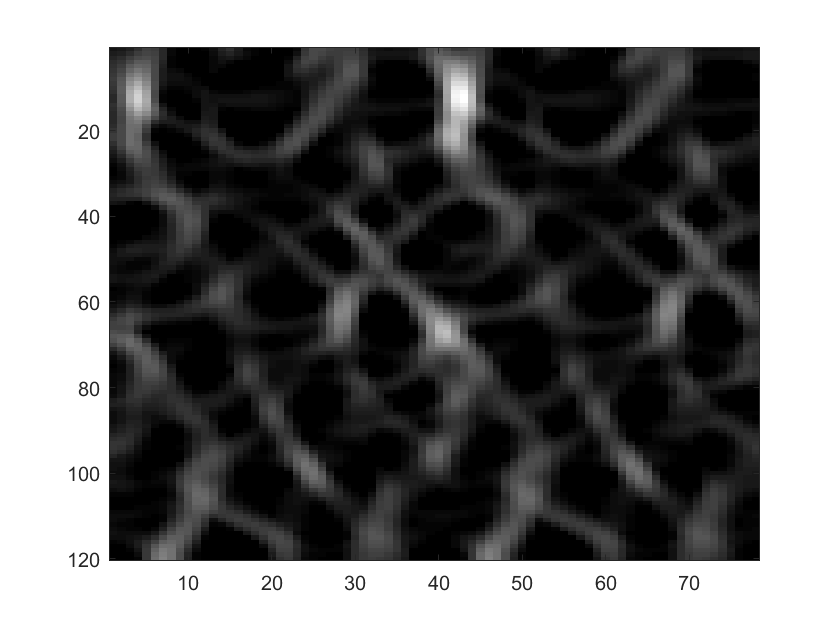


blurSigma = 2;
[ridgeBW ridge ridge_nms ] = cannyridgefilter(im,'BlurSigma',blurSigma,'NMS-con','4-con');
imagesc(ridge);
colormap gray;

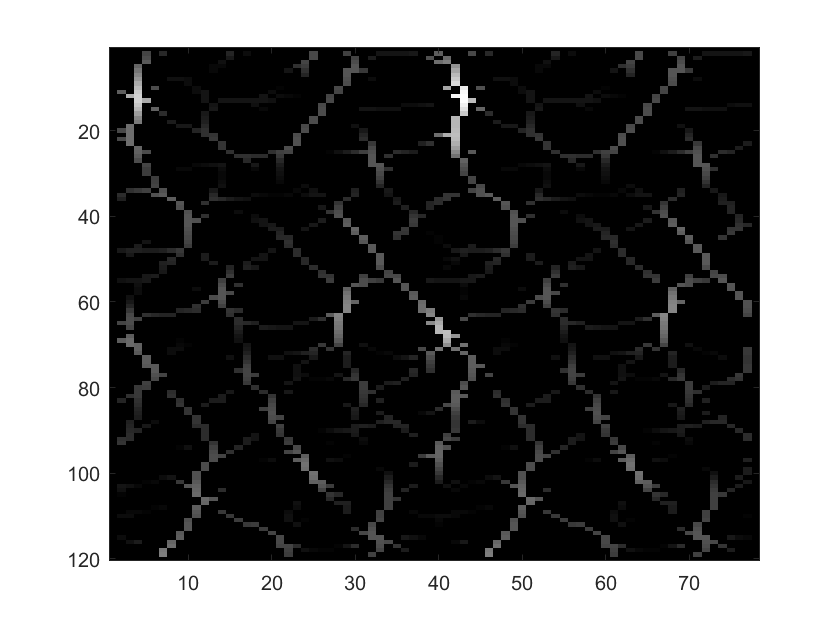

imagesc(ridge_nms);
colormap gray;

looks pretty good

What if we try 45 degrees too?

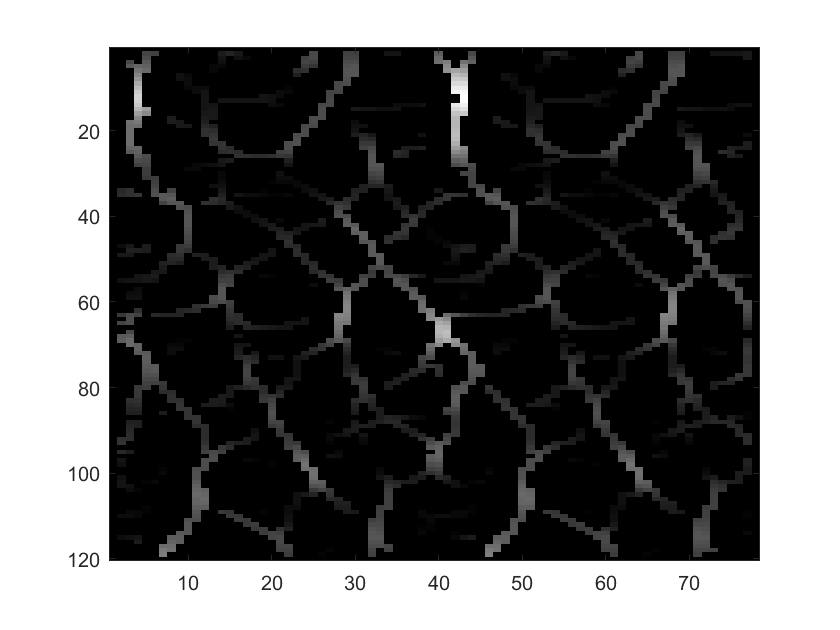

[ridgeBW ridge ridge_nms_8con ] = cannyridgefilter(im,'BlurSigma',blurSigma,'NMS-con','8-con');
imagesc(ridge_nms_8con);
colormap gray;

Ridge BW has the hysteresis applied too:

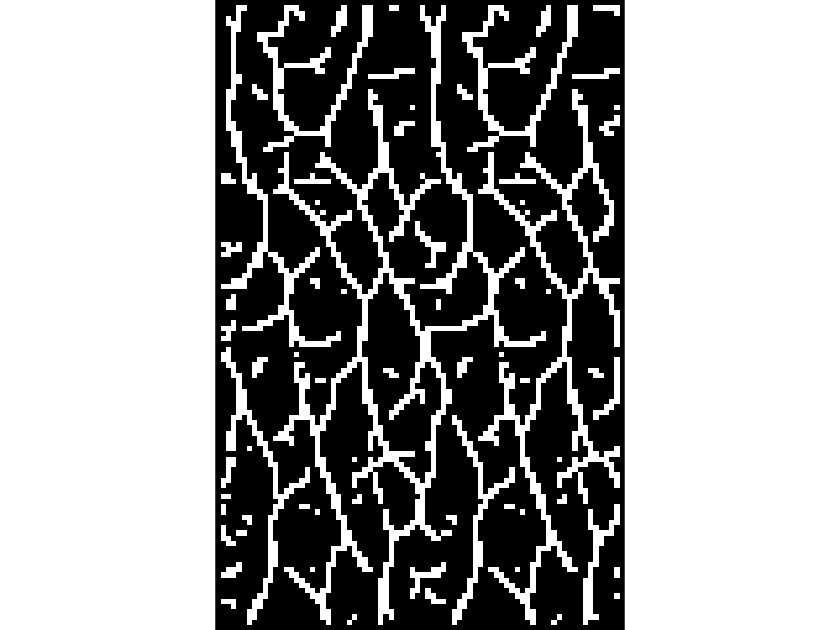

imshow(ridgeBW)

Looks good

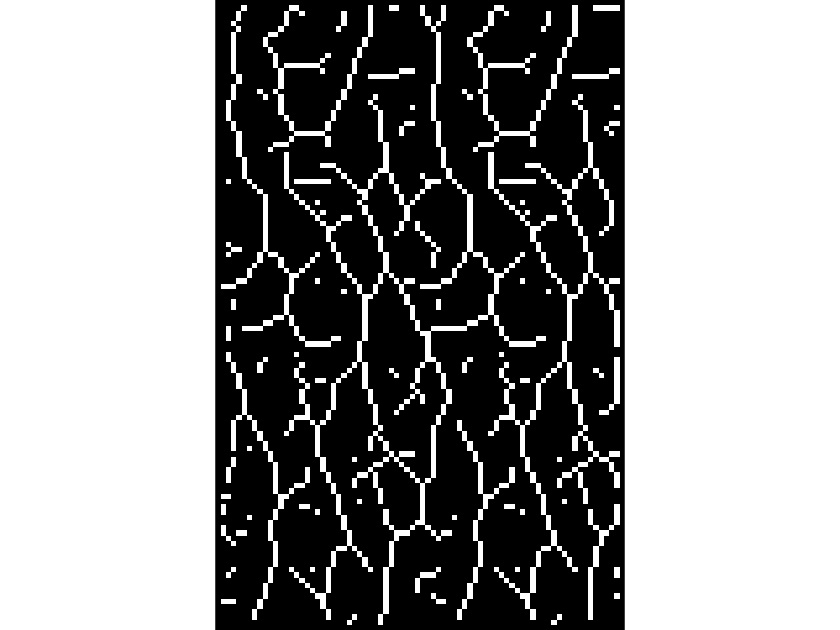

imshow(bwskel(ridgeBW))

%what if we just do horizontal NMS makes the most sense for kymogrpahs

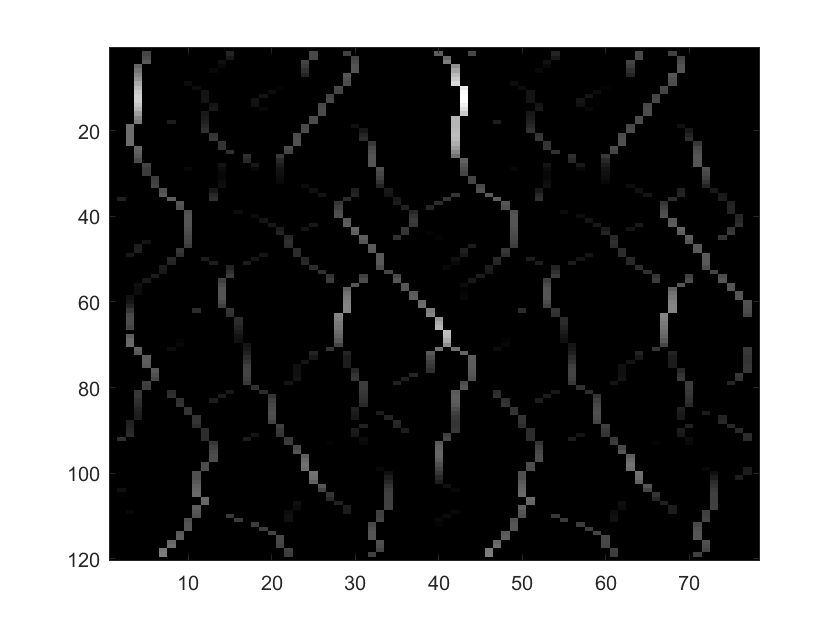

[ridgeBW ridge ridge_nms_horz ] = cannyridgefilter(im,'BlurSigma',blurSigma,'NMS-con','horz');
imagesc(ridge_nms_horz);

just horizontal connectivity but with hysteresis applied:

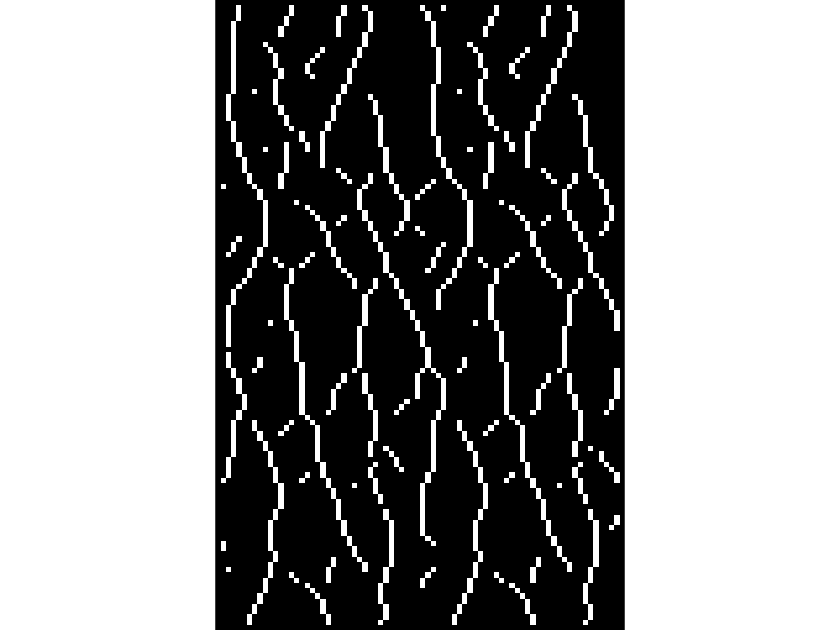

imshow(ridgeBW)

This might be a bit harsh compared to the 4-con NMS. Depends on the tracking method in the end.

What about horz connectivity with hough transform?

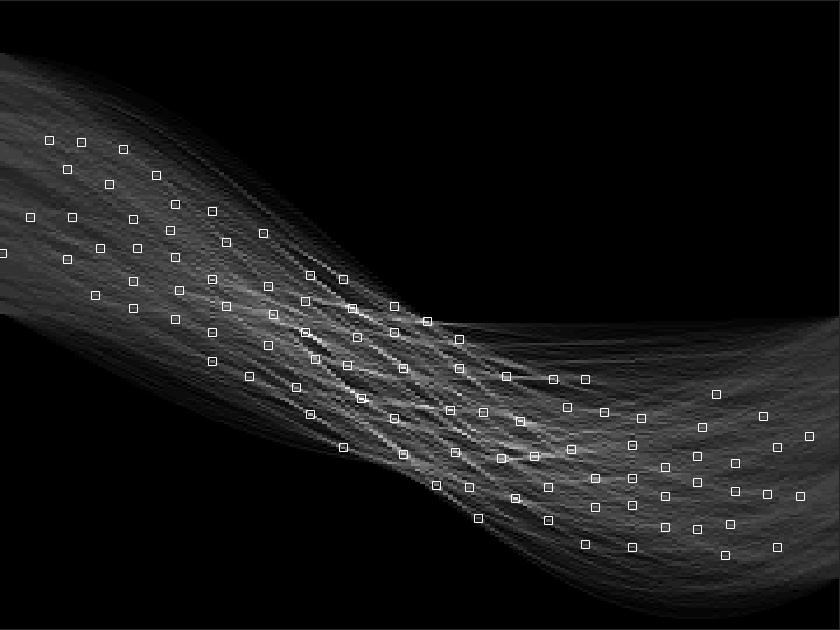

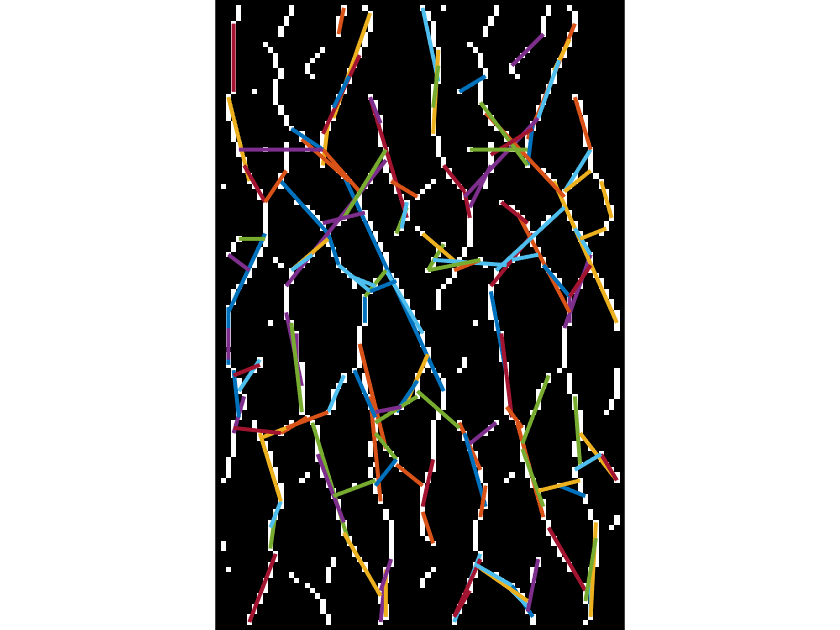

suppressNHood = [21 11];%rho theta
%suppressNHood = size(H)/10; %rho theta
thresh=0.3;
fillgap=5;
minlen=5;
[H theta_hough rho_hough]=houghline(ridgeBW,suppressNHood,thresh,fillgap,minlen);

horz canny ridge with lower th> - no look at the nms image it's basically the same

%

what about radon?

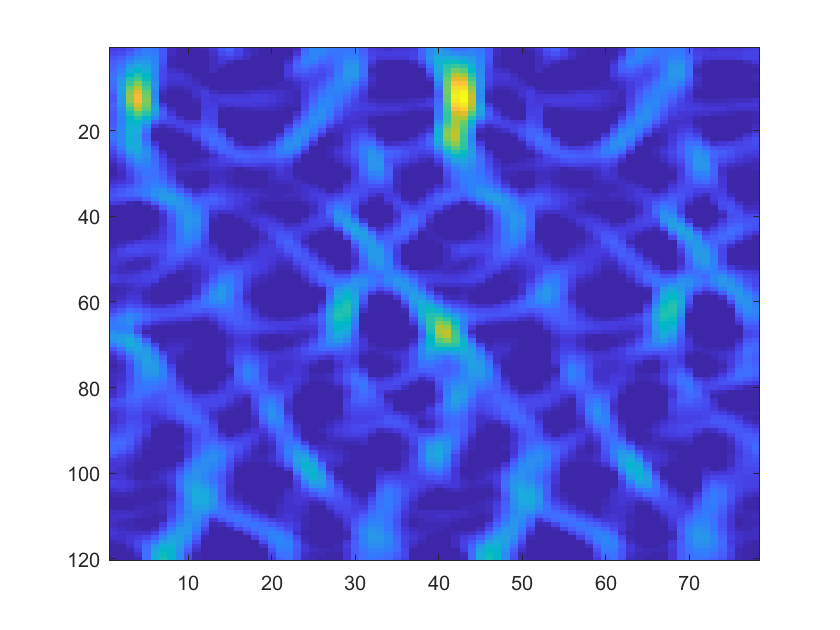

figure;imagesc(ridge)

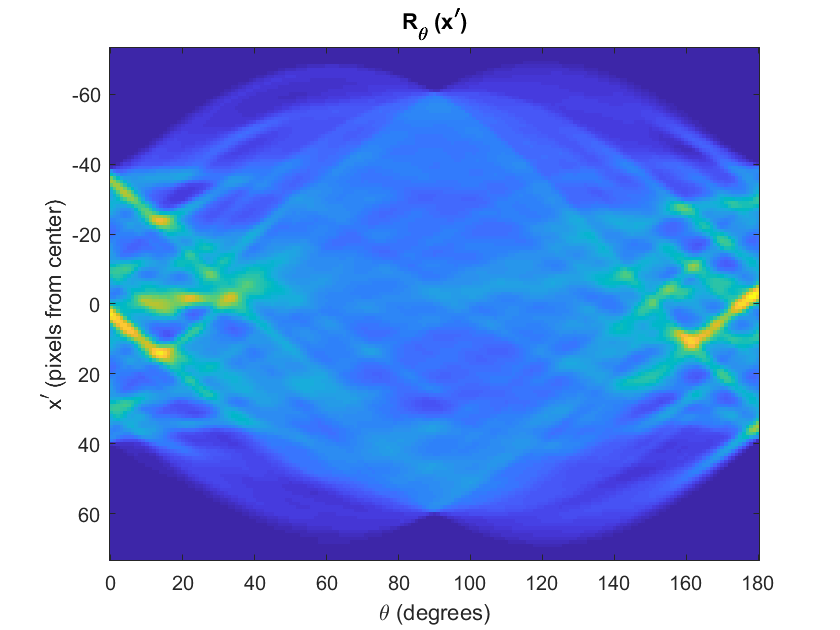

figure
[R, xp] = radon(ridge,0:180);
theta_radon= 0:180;
rho_radon = xp;
imagesc(0:180, xp, R)
xlabel('\theta (degrees)');
ylabel('x^{\prime} (pixels from center)');
title('R_{\theta} (x^{\prime})');

Hough peaks?

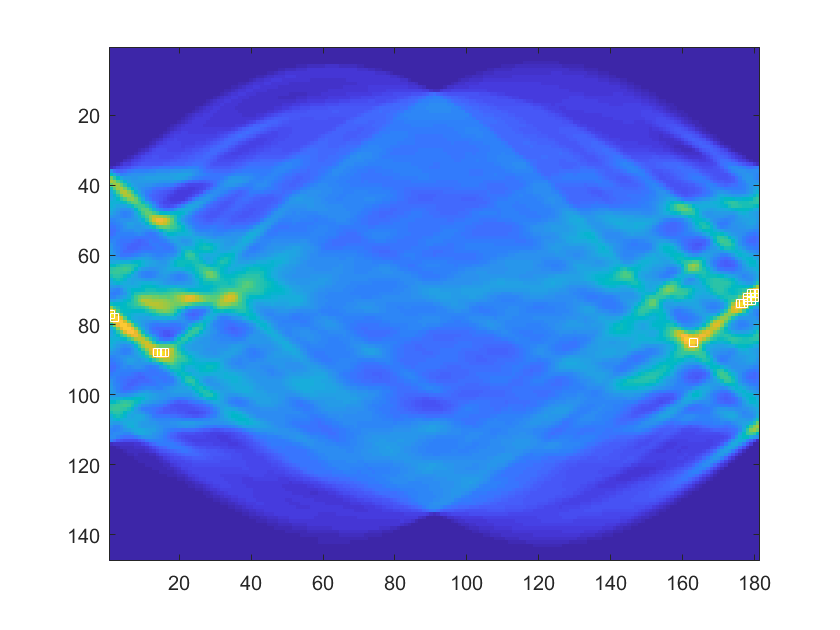

MAXPEAK =1000;
suppressNHood = size(R)/20; %rho theta
suppressNHood = [0 0]; %rho theta
thresh=0.9;
th = ceil(thresh*max(R(:)));
suppressNHood = max(2*ceil(suppressNHood/2) + 1, 1);
P  = houghpeaks(round(R),MAXPEAK,'threshold',th,'NHoodSize', suppressNHood);

x = P(:,2); y = P(:,1);
figure;
imagesc( R)
hold all;
plot(x,y,'s','color','white');

sucks

Starting point here:

[https://github.com/svkucheryavski/nscradon](https://github.com/svkucheryavski/nscradon)

Compare hough and radon results

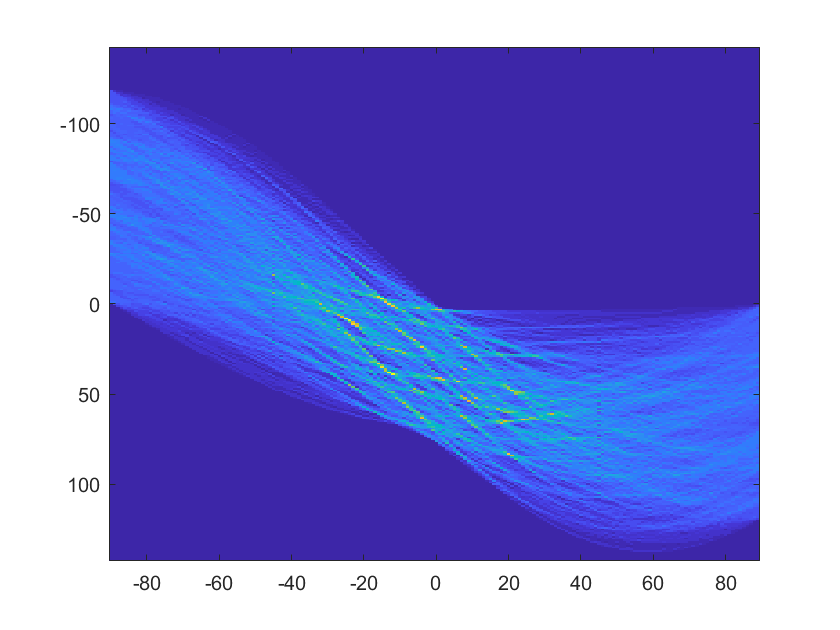

figure;
imagesc(theta_hough,rho_hough,H)

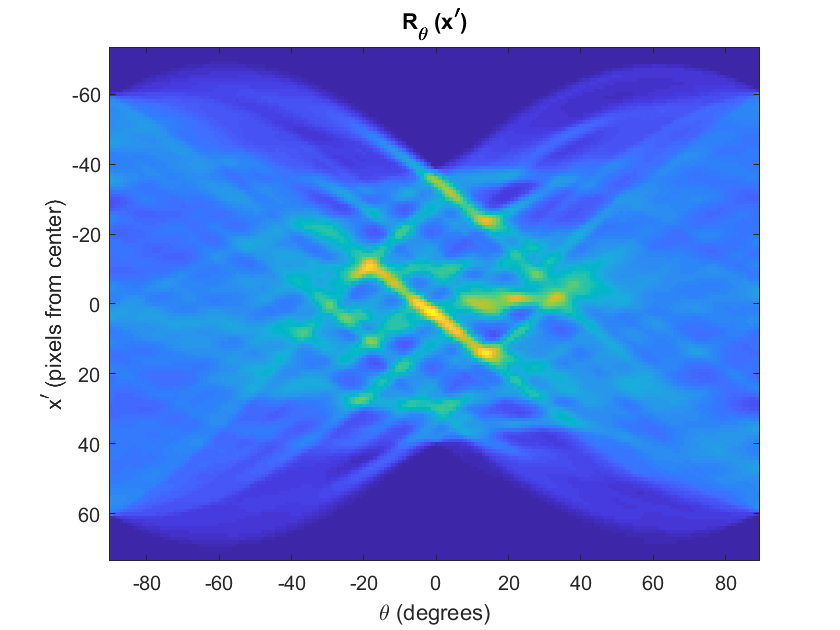

figure
[R, rho_radon] = radon(ridge,theta_hough);
imagesc(theta_hough, rho_radon, R)
xlabel('\theta (degrees)');
ylabel('x^{\prime} (pixels from center)');
title('R_{\theta} (x^{\prime})');

tiffwrite('testRadon.tif',R);

imagej find peaks looks promising, prominence > 100:

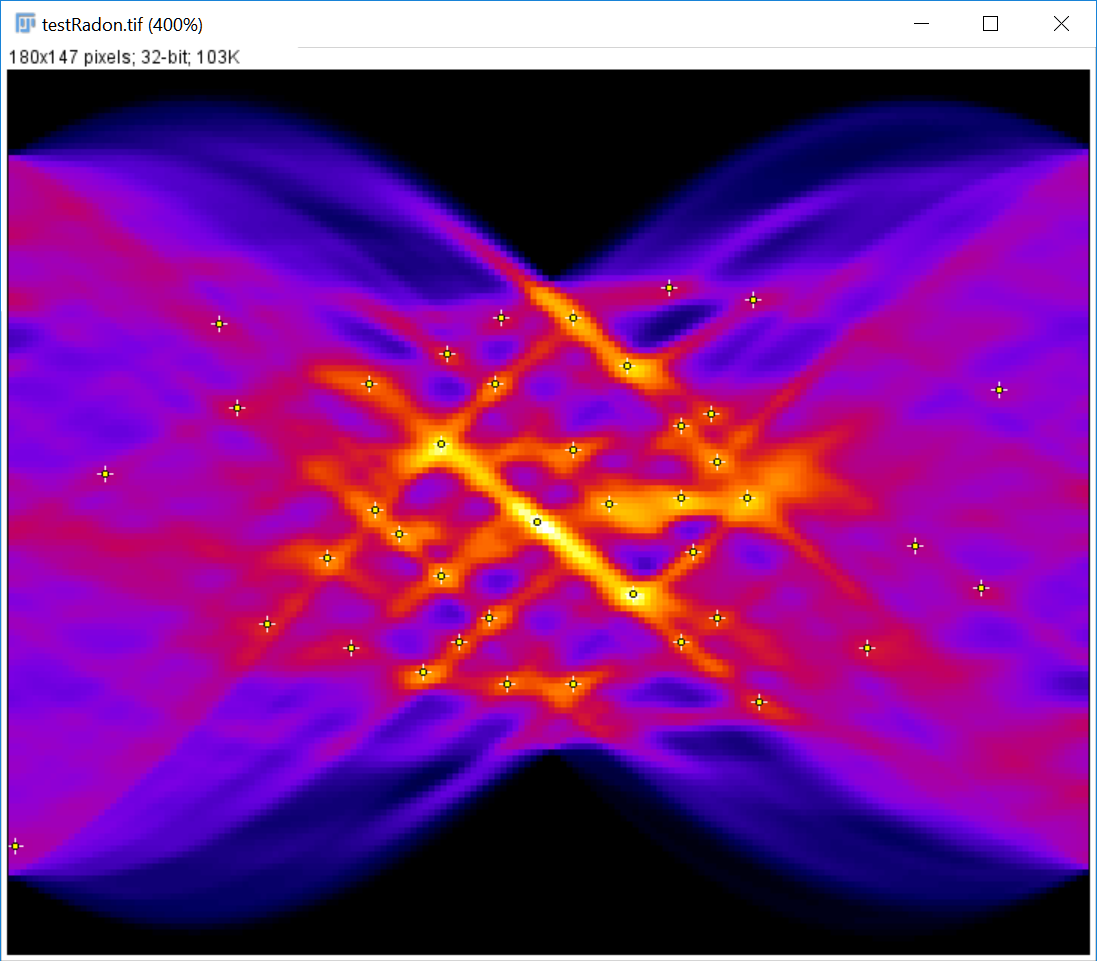

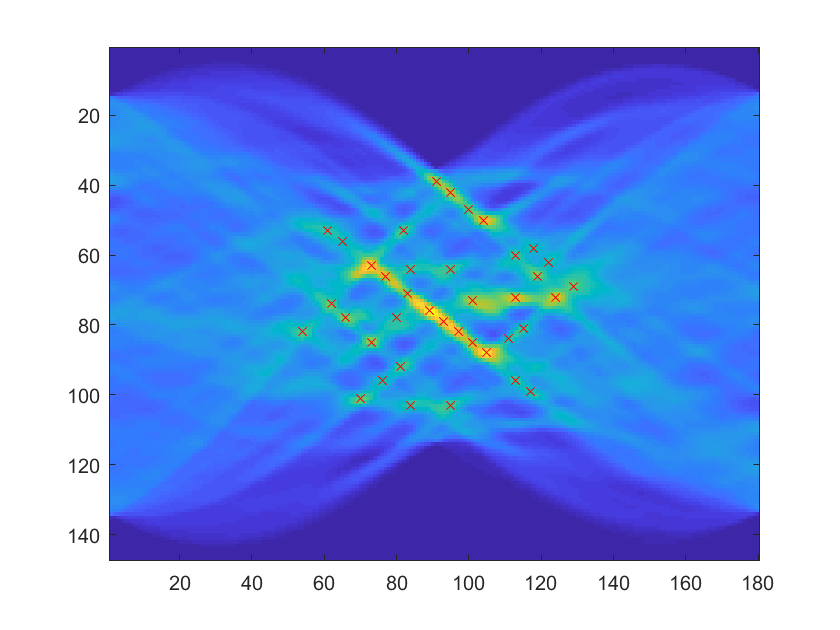

ispeak = findpeaksn(R,[1 1],round(0.5*max(R(:))),5);
[y,x] = find(ispeak);
figure;
imagesc( R)

hold all;
plot(x,y,'rx');

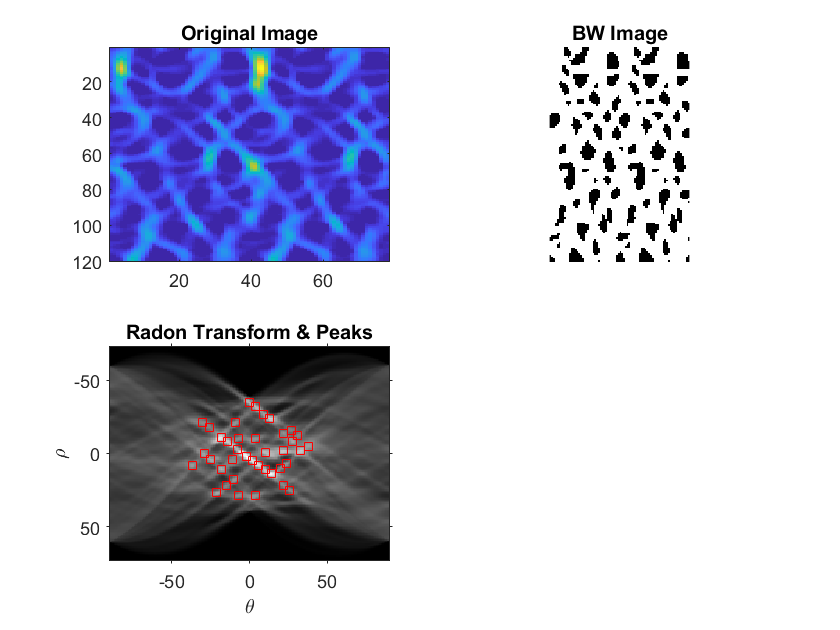

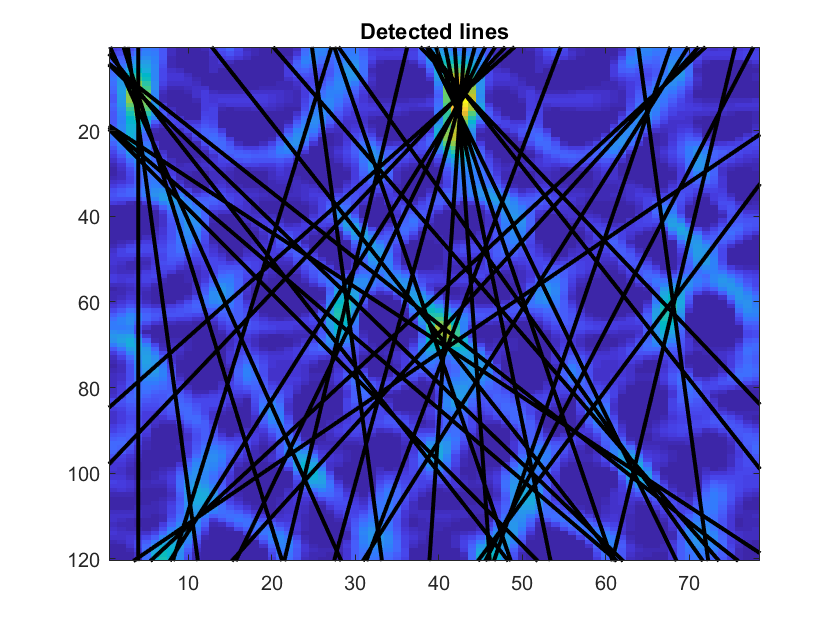

ans = 	1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

th = 0.5;
minsep =5;
getradonline(ridge,th,minsep)

It's stil kind of shit

Also what does the radon or hough transform look on the nms data?

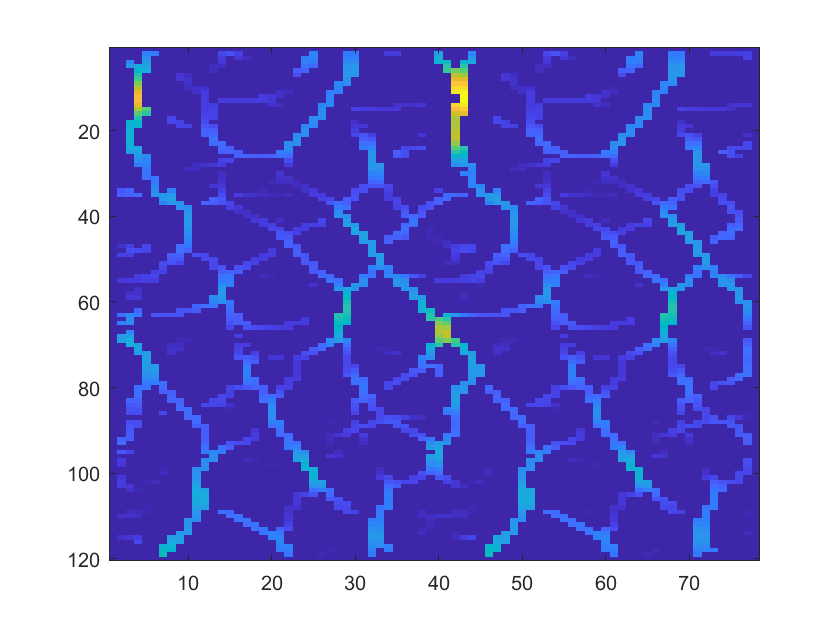

[ridgeBW ridge nms ] = cannyridgefilter(im,'BlurSigma',blurSigma,'NMS-con','8-con');
imagesc(nms)

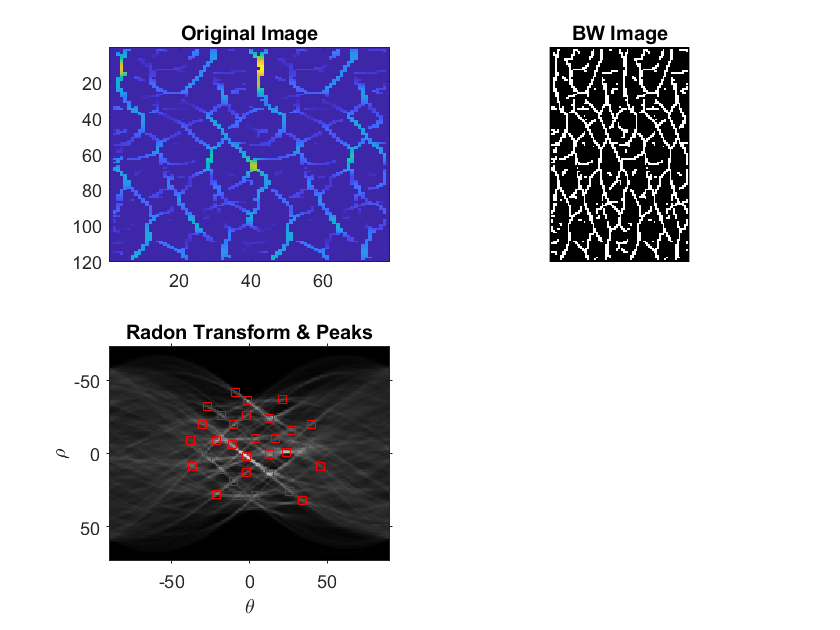

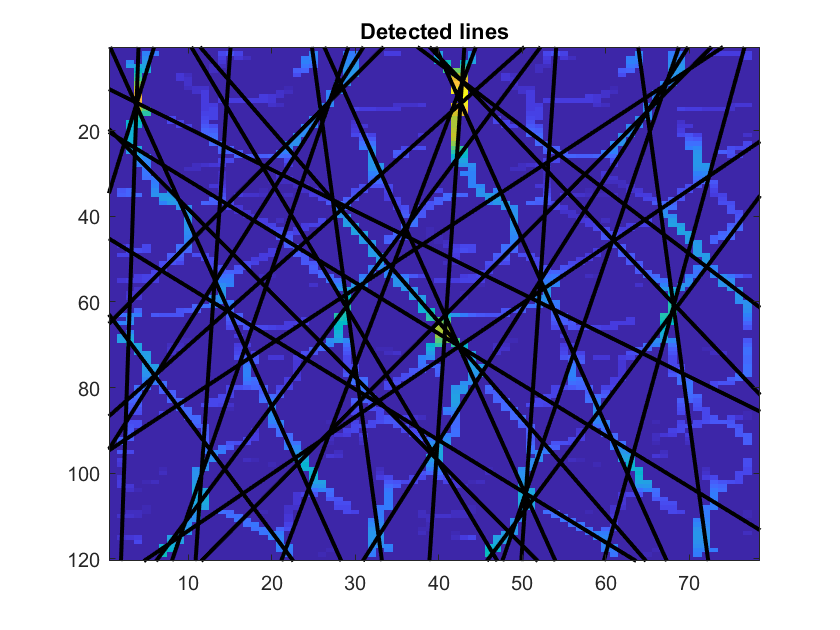

th = 0.3;
minsep =10;
R = getradonline(nms,th,minsep);

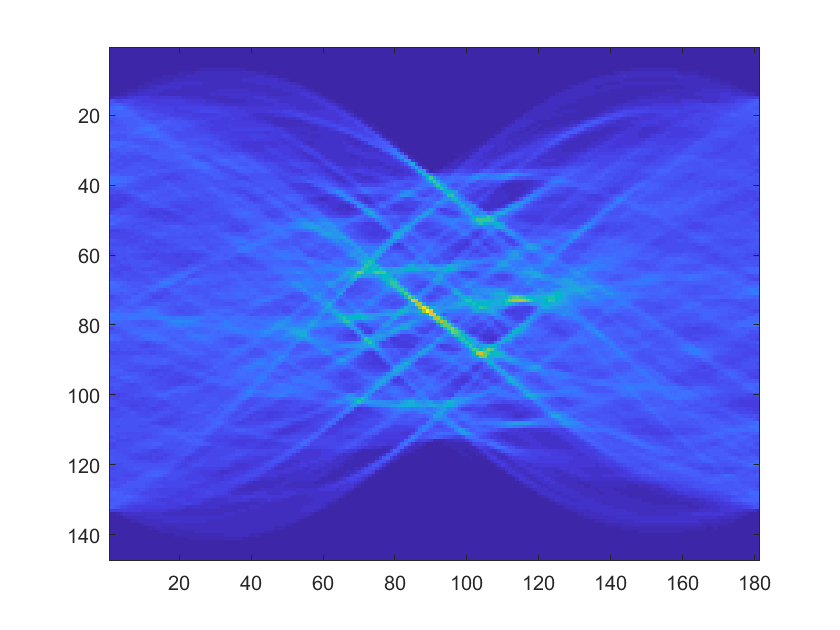

imagesc(R)

What if we do horz nms on the 8 con image (funky but allows for better connectivity)

[ridgeBW ridge nms ] = cannyridgefilter(im,'BlurSigma',blurSigma,'NMS-con','8-con');
imagesc(nms);

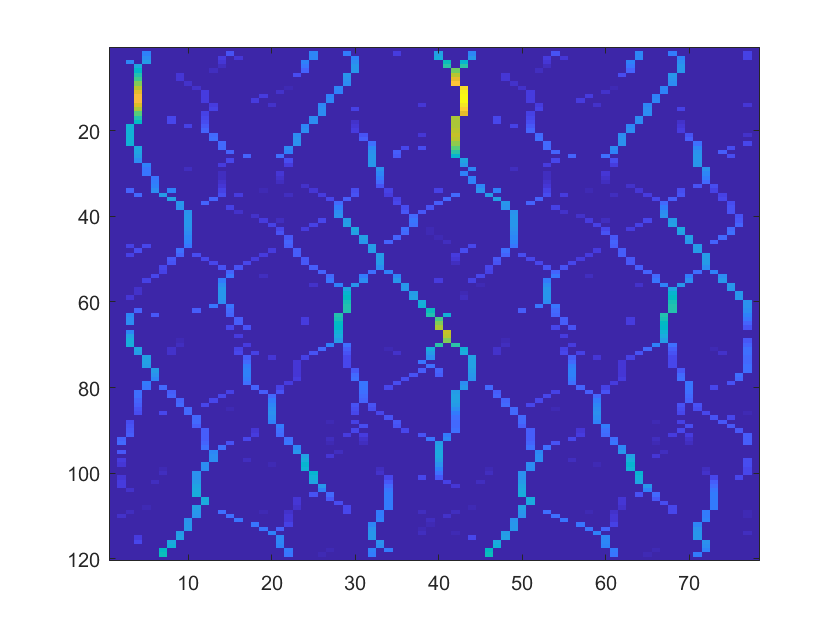

nms2 = nmsfilter(nms,'horz');
imagesc(nms2)

compare with horz nms

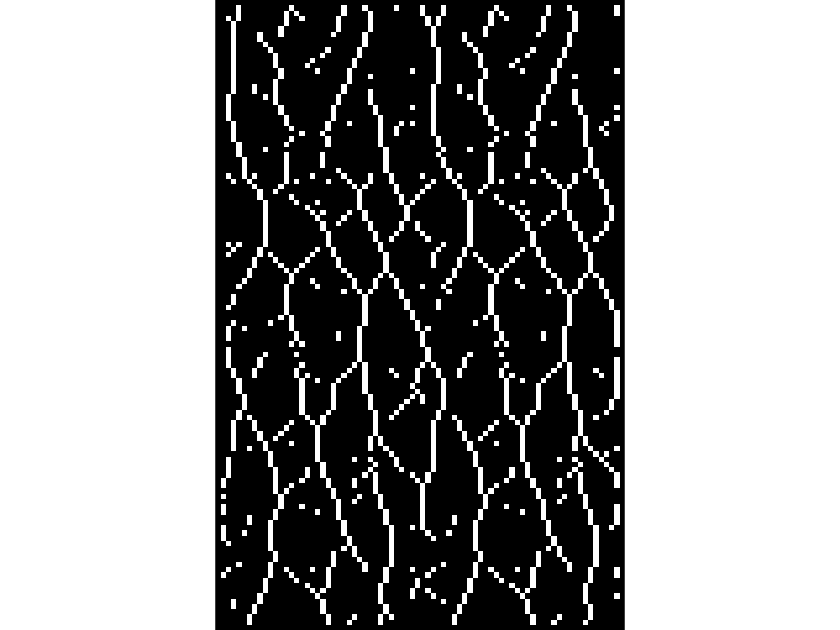

bw_nms2 = nms2;
bw_nms2(bw_nms2>0)=1;
imshow(bw_nms2);
title('8con post-filtered horz')



[horzBW ] = cannyridgefilter(im,'BlurSigma',blurSigma,'NMS-con','horz');
imshow(horzBW)
title('horz conn')

the 8 conn horz filtered is noiser but probably more appropriate for tracking as it is less harsh

I think the only chance for this is some sort of harsh global jaqaman/ kalman type filter in 1d

what if we save the BW image as a 1 d stack?

try the trackmate tracker

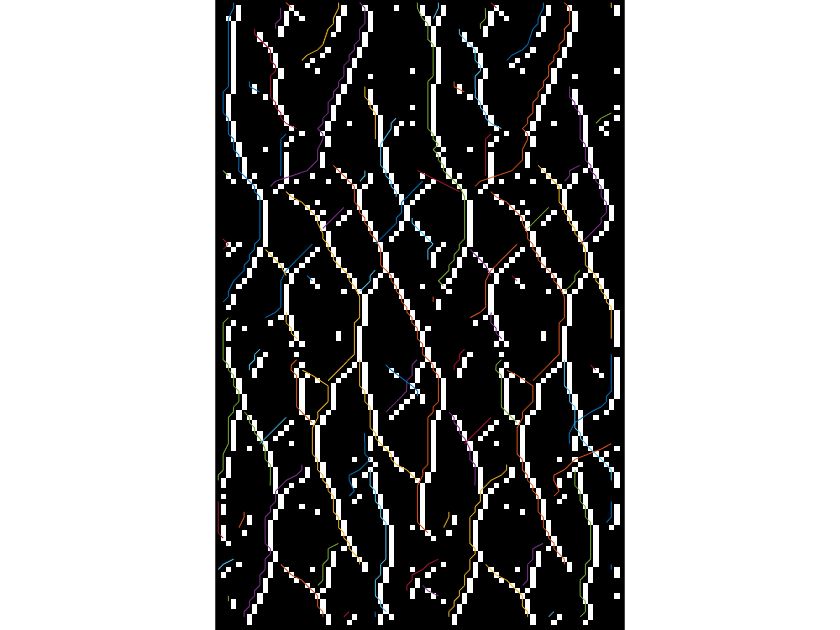

bw_nmsOut = cast(bw_nms2*255,'uint8');
tiffwrite('bwRidge.tif',bw_nmsOut);
BW_3d = permute(bw_nmsOut,[3 2 1]);
tiffwrite('bwRidgeStack.tif',BW_3d);
%tracked with trackmate
[tracks] = importTrackMateTracks('bwRidgeStack_Tracks.xml');
figure;
imshow(bw_nms2);
hold all;
for ii = 1:numel(tracks)
    plot(tracks{ii}(:,2)/.065,tracks{ii}(:,1));
end

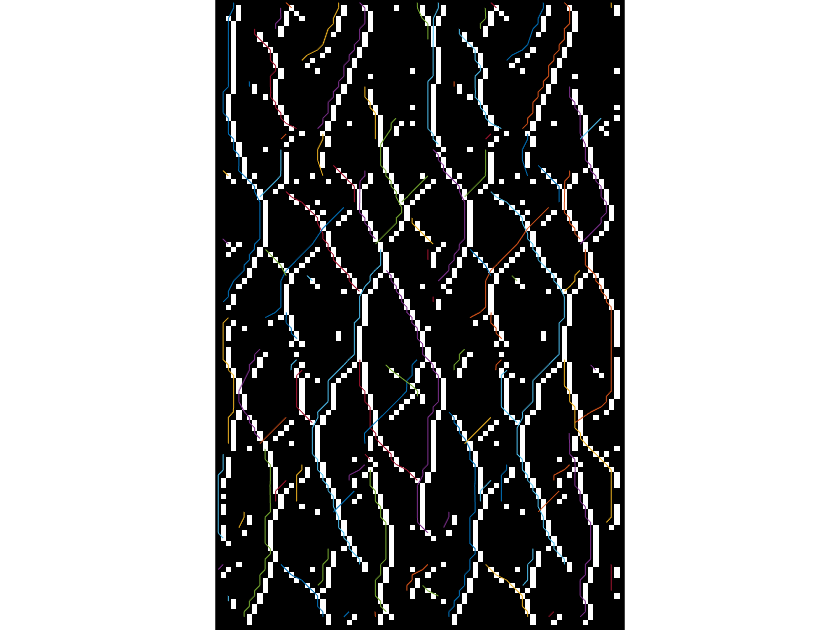

%tracked with trackmate
[tracks] = importTrackMateTracks('bwRidgeStack_Tracks_0.1-0.1-4.xml');
figure;imshow(bw_nms2);
hold all;
for ii = 1:numel(tracks)
    plot(tracks{ii}(:,2)/.065,tracks{ii}(:,1));
end

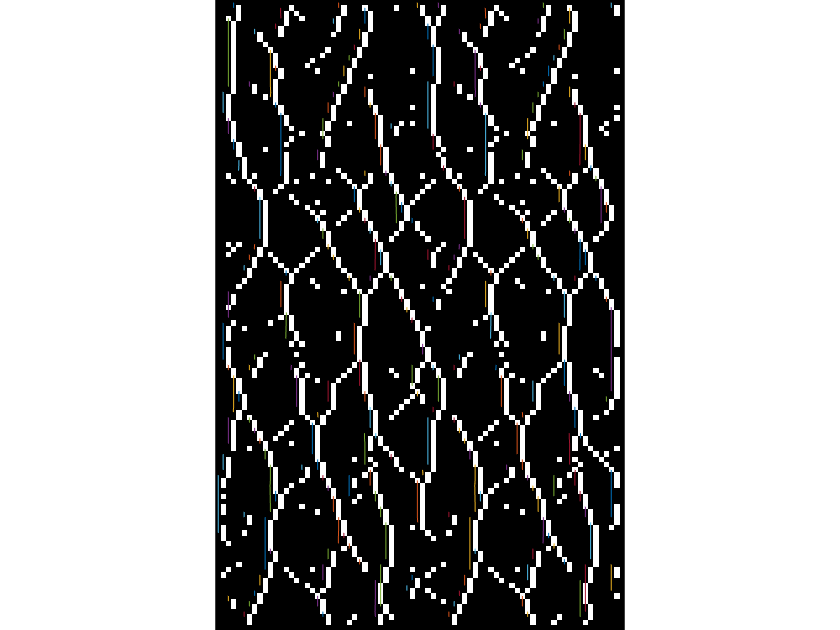

%tracked with trackmate
[tracks] = importTrackMateTracks('bwRidgeStack_Tracks_0.05-0.05-4.xml');
figure;imshow(bw_nms2);
hold all;
for ii = 1:numel(tracks)
    plot(tracks{ii}(:,2)/.065,tracks{ii}(:,1));
end

kind of promising and kind of incredibly stupid